# Live Script Métodos Numéricos para um PVI

26/03/2021  Arménio Correia  armenioc@isec.pt

26/04/2021  Nuno Santos      a2019110035@isec.pt

26/04/2021  Pedro Nogueira   a2020136533@isec.pt

26/04/2021  João Almeida     a2020144466@isec.pt

clear
clc
syms y(t)
f =@(t,y) -2*t*y

f = function_handle with value:
    @(t,y)-2*t*y


a = 1

a = 1

b = 1.5

b = 1.5000

n = 10

n = 10

y0 = 2

y0 = 2


yEuler = MEuler(f,a,b,n,y0);
yEulerM = MEulerMelh(f,a,b,n,y0);
yRK2 = RK2(f,a,b,n,y0);
yRK4 = RK4(f,a,b,n,y0);
yODE45 = ODE45(f,a,b,n,y0);
yDormandPrince = DormandPrince(f,a,b,n,y0);

%Função exata
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = 2\,\mathrm{e}\,{\mathrm{e}}^{-t^{2}}$$


g = @(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);

erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
erroRK2 = abs(yExata-yRK2);
erroRK4 = abs(yExata-yRK4);
erroODE45 = abs(yExata-yODE45);
erroDormandPrince = abs(yExata-yDormandPrince);

tabela = [t.',yExata.',yEuler.',yEulerM.',yRK2.',yRK4.',yODE45.',yDormandPrince.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','EulerM','RK2','RK4','ODE45','DormandPrince'})

ans = 11×8 table
     t       Exata      Euler     EulerM       RK2        RK4       ODE45     DormandPrince
    ____    _______    _______    _______    _______    _______    _______    _____________

       1          2          2          2          2          2          2             2   
    1.05     1.8052        1.8        1.8     1.8055     1.8052     1.8052        1.8052   
     1.1     1.6212      1.611      1.611     1.6218     1.6212     1.6212        1.6212   
    1.15     1.4487     1.4338     1.4338     1.4496     1.4487     1.4487        1.4487   
     1.2     1.2881     1.2689     1.2689     1.2893     1.2881     1.2881        1.2881   
    1.25     1.1396     1.1166     1.1166      1.141     1.1396   

tabela2 = [erroEuler.',erroEulerM.',erroRK2.',erroRK4.',erroODE45.',erroDormandPrince.'];
array2table(tabela2,"VariableNames",{'erroEuler','erroEulerM','erroRK2','erroRK4','erroODE45','erroDormandPrince'})

ans = 11×6 table
    erroEuler     erroEulerM     erroRK2       erroRK4      erroODE45     erroDormandPrince
    __________    __________    __________    __________    __________    _________________

    4.4409e-16    4.4409e-16    4.4409e-16    4.4409e-16    4.4409e-16       4.4409e-16    
     0.0051563     0.0051563     0.0003437    1.7992e-07    5.2706e-10       5.2706e-10    
      0.010168      0.010168    0.00066702     3.683e-07    1.1446e-09       1.1446e-09    
      0.014882      0.014882    0.00096526    5.6273e-07    1.8514e-09       1.8514e-09    
      0.019169      0.019169     0.0012344    7.6031e-07    2.6423e-09       2.6423e-09    
       0.02293       0.02293     0.0014713    9.5778e-07    3.5083e-09       3.5083e-09    
      0.026096      0.026096     0.0016735

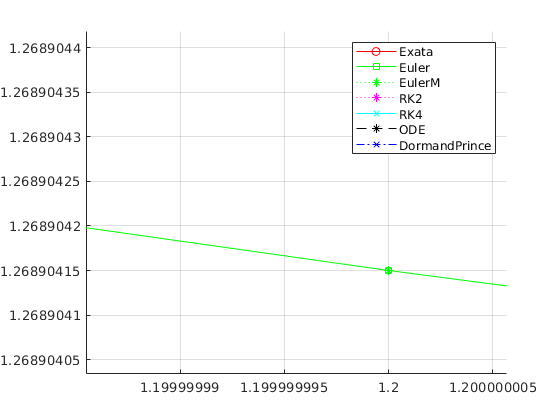

hold on
plot(t,yExata,"-ro")
plot(t,yEuler,"-gs")
plot(t,yEulerM,"g*:")
plot(t,yRK2,"m*:")
plot(t,yRK4,"cx-")
plot(t,yODE45,"k*--")
plot(t,yDormandPrince,"bx-.")
hold off
grid on
legend('Exata','Euler','EulerM','RK2','RK4','ODE','DormandPrince')